# Multidimensional scaling

In this one, we try to apply the theory of multidimensional scaling onto our data. For this we need to establish the correct dissimilarity matrix that should be applicable for the algorithm. After that, we want to visualize the embedding we get from the mds algorithm.

A first example is given in the documentation of classical multidimensional scaling (https://de.mathworks.com/help/stats/introduction-to-classical-multidimensional-scaling.html).

rng default;  % For reproducibility
X = [normrnd(0,1,10,3),normrnd(0,.1,10,1)];
D = pdist(X,'euclidean');

[Y,stress] = mdscale(D,2);
stress

stress = 0.0138

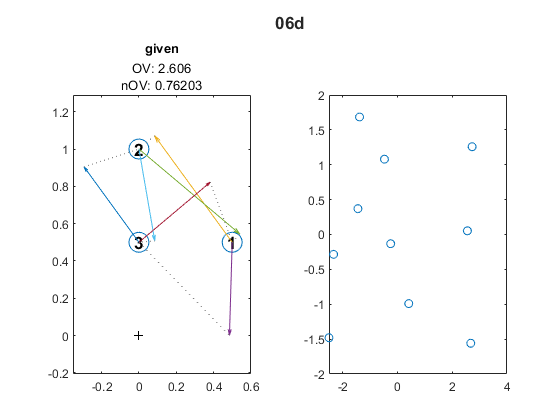

plot(Y(:,1),Y(:,2),'o');


[Y1,eigvals] = cmdscale(D);
p = size(Y1,2)

p = 4

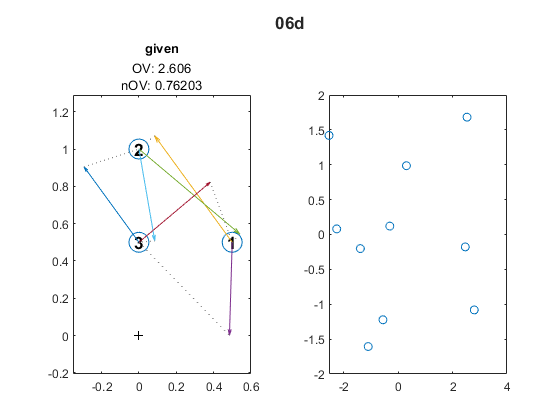

plot(Y1(:,1),Y1(:,2),'o');

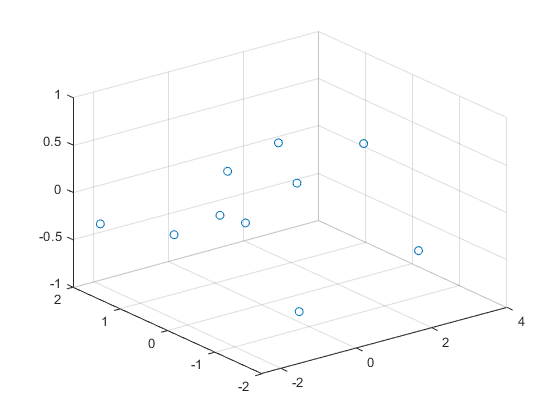

plot3(Y1(:,1),Y1(:,2),Y1(:,3),'o');
grid on

For testing we generate some random dissimilarity matrix of 6 points and apply the mds function for 2 Dimensions on it.

D = [1 0.1 0.03 0.3 1.4 1 3.1 33.9 2 31 3.3 2.1 21 0.3 0.1];
Dsq = squareform(D);

For 2 Dimensions:

[Y,stress] = mdscale(D,2);
stress

stress = 0.0568

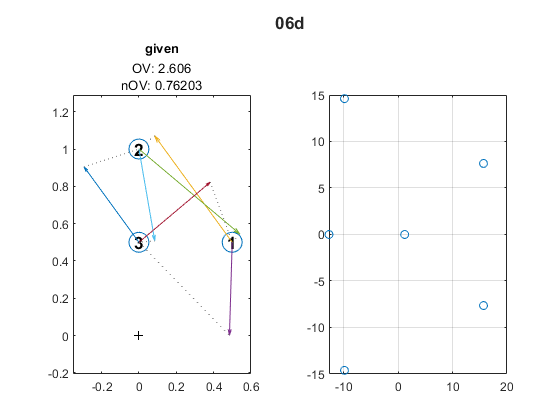

plot(Y(:,1),Y(:,2),'o');
grid on

For 3 Dimensions:

[Y,stress] = mdscale(D,3);
stress

stress = 9.1472e-07

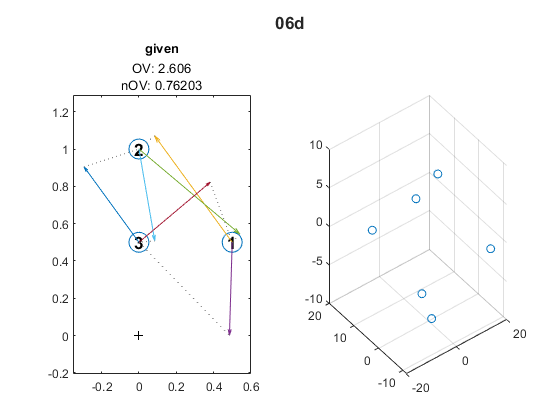

plot3(Y(:,1),Y(:,2),Y(:,3),'o');
grid on

Now let's use one example graph in our dataset as a starting point to generate good embeddings. The main question is, how we get from a matrix of angle estimates **A** to the dissimilarity matrix **D**. For this we might want to read up on the theory behind the MDS.

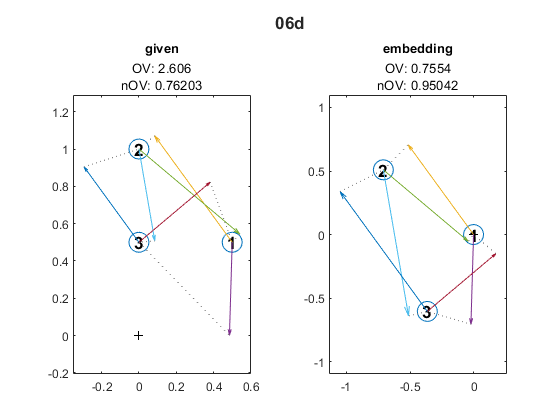

load materials\06d.mat edges n
plotCompare('06d',[0,0]);

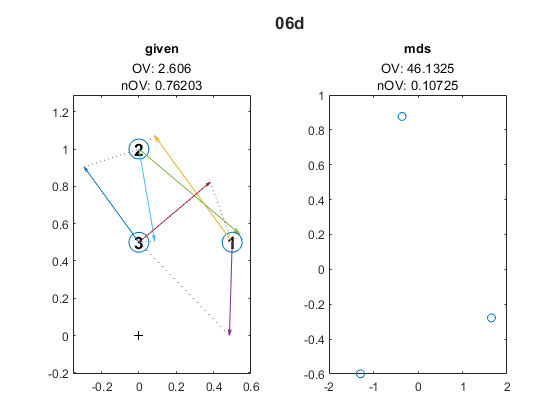

A = sparse(edges(:,2),edges(:,3),edges(:,5),n,n);
D = pdist(A);
[Y,stress] = mdscale(D,2);

plot(Y(:,1),Y(:,2),'o');
title("mds");
subtitle(append("OV: ",string(ObjF(Y,edges)),newline,"nOV: ",string(restrictedObjFN(Y,edges))),'FontWeight',"normal");


figure